class1 = 'TURMER';
class2 = 'LUSMEG';

filtBanks.fs44100 = gammatoneFilterBank([50 10000],64,44100);
filtBanks.fs48000 = gammatoneFilterBank([50 10000],64,48000);
filtBanks.fs96000 = gammatoneFilterBank([50 10000],64,96000);
filtBanks.fs88200 = gammatoneFilterBank([50 10000],64,88200);

[XTrain, YTrain] = createFeatureCells(TURMER_train40,LUSMEG_train40,class1,class2);
XTrainFs = vertcat(TURMER_trainFs40,LUSMEG_trainFs40);
[XTest, YTest] = createFeatureCells(TURMER_test40,LUSMEG_test40,class1,class2);
XTestFs = vertcat(TURMER_testFs40,LUSMEG_testFs40);

XTrainMrcgBase = cellfun(@(a,b) extractMrcg(a,b,filtBanks),XTrain,XTrainFs,"UniformOutput",false);

XTrainMrcgNumeric = cell2Matrix(XTrainMrcgBase);

[XTrainMrcg,YTrainMrcg,XValMrcg,YValMrcg] = createValidationSplit(XTrainMrcgNumeric,YTrain,"Split",0.05);

XTestMrcgBase = cellfun(@(a,b) extractMrcg(a,b,filtBanks),XTest,XTestFs,"UniformOutput",false);
XTestMrcgNumeric = cell2Matrix(XTestMrcgBase);

cnnMrcgEvalCell = {};

idx = 1;
for i = 1:length(XTrainMrcgBase)   
    if i <= 1107
        type = 'TURMER';
    elseif i == 1108
        type = 'LUSMEG';
        idx = 1;
    else
        type = 'LUSMEG';
    end
    im = XTrainMrcgBase{i};
    imwrite(im,sprintf('mrcg/training/%s/mrcg_%d.png',type,idx));
    idx = idx + 1;
end

## Model 0

layers0 = [...
    imageInputLayer(size(XTrainMrcgNumeric,[1 2 3]))
    convolution2dLayer(5,20)
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(2)
    softmaxLayer
    classificationLayer
];

maxEpochs = 30;
options0 = trainingOptions("adam", ...
    "MiniBatchSize",128, ...
    "Plots","training-progress", ...
    "MaxEpochs",maxEpochs, ...
    "ValidationData",{XValMrcg,YValMrcg}, ...
    "Verbose",0);

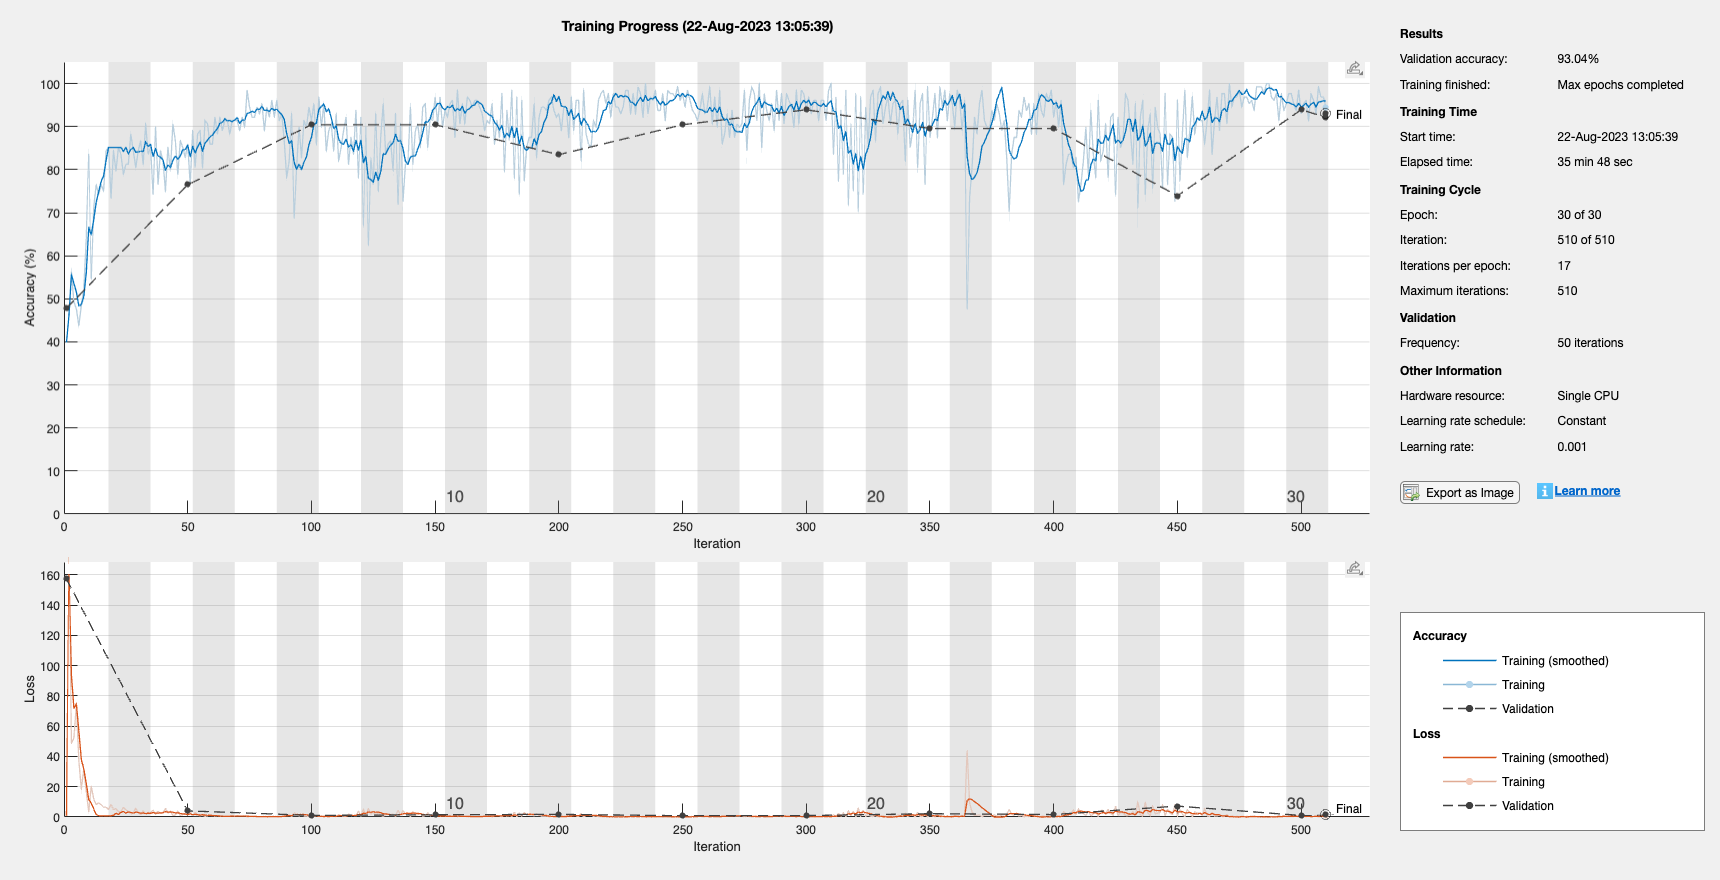

cnnMrcg0 = trainNetwork(XTrainMrcg,YTrainMrcg,layers0,options0);

Took about 70 seconds per epoch

eval0 = generateEvaluationCell(cnnMrcg0,0,XTestMrcgNumeric,YTest,class1);
cnnMrcgEvalCell = [cnnMrcgEvalCell;eval0];

## Model 1: Ruff et al.

imds = imageDatastore('mrcg/training','IncludeSubfolders',true,"LabelSource","foldernames");

layers1 = [...
    imageInputLayer(size(preview(imds),[1 2 3]))
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2)
    dropoutLayer(0.2)
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2)
    dropoutLayer(0.2)
    convolution2dLayer(3,64,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2)
    dropoutLayer(0.2)
    convolution2dLayer(3,64,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2)
    dropoutLayer(0.2)
    fullyConnectedLayer(64)
    reluLayer
    dropoutLayer(0.5)
    batchNormalizationLayer
    fullyConnectedLayer(2)
    softmaxLayer
    classificationLayer
];


maxEpochs = 30;
options1 = trainingOptions("adam", ...
    "MiniBatchSize",128, ...
    "Plots","training-progress", ...
    "MaxEpochs",maxEpochs, ...
    "Verbose",0);

% options1 = trainingOptions("adam", ...
%     "MiniBatchSize",128, ...
%     "Plots","training-progress", ...
%     "MaxEpochs",maxEpochs, ...
%     % "ValidationData",{XValMrcg,YValMrcg}, ...
%     "Verbose",0);

cnn1 = trainNetwork(imds,layers1,options1);

eval1 = generateEvaluationCell(cnn1,1,XTestMrcgNumeric,YTest,class1);
cnnMrcgEvalCell = [cnnMrcgEvalCell;eval1];

function mrcgFeature = extractMrcg(signal,fs,filtBanks)
gt = filtBanks.(sprintf('fs%d',fs));
audioOut = gt(signal);
mrcgFeature = mrcg(audioOut,fs);
del = audioDelta(mrcgFeature);
ddel = audioDelta(del);
mrcgFeature = [mrcgFeature;del;ddel];
end

function [XTrain, YTrain, XValidation, YValidation] = createValidationSplit(X, Y, nva)
arguments
X
Y
nva.Split = 0.3
end

numSamples = size(X, 4);

cv = cvpartition(numSamples, 'HoldOut', nva.Split);
trainIndices = training(cv);
validationIndices = test(cv);

XTrain = X(:,:,1,trainIndices);
YTrain = Y(trainIndices);

XValidation = X(:,:,1,validationIndices);
YValidation = Y(validationIndices);
end

function matrix = cell2Matrix(cell)
matrix = zeros(size(cell{1},1),size(cell{1},2),1,numel(cell));
for row = 1:numel(cell)
matrix(:,:,1,row) = cell{row};
end
end

function evalCell = generateEvaluationCell(model,archNumber,XTest,YTest,posClass)
[auc,accuracy,ROCX,ROCY] = evaluateNN(model,XTest,YTest,posClass);
evalCell = {archNumber,auc,accuracy,ROCX,ROCY};
end